all_amino = [h_aminoacid;aminoacid];
length(all_amino)

ans = 23

ma = multialign(char(all_amino(:,1)))

ma = 23×604 char array
    '--------------------------------------------------M-----------------------------------------------------------------------------------ANLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNVVGPYGLLQPFADAMKLFTKEPLKPATSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTL---------------------------------LMSGSFNLSTLITTQEHLWLLLPSWPLAMMWFISTLAETNRTPFDLAEGESELVSGFNIEYAAGPFALFFMAEYTNIIMMNTLTTTIFLGTTYDALSPELYTTYFVTKTLLLTS---------------------------------------------------------------------------LFLWIRTAYPRFRYDQLMHLLWKNFLPLTLALLMWYVSMPITISSIPPQT*----------------------------------------------'
    'MNENLFASFIAPTILGLPAAVLI-------------------------------------------------------------------ILFPPLLIPTSKYLINNRLITTQQWLIKLTSKQMMTMHNTKGRTWSLMLVS---------------------------------------LIIFIATTNLLGLLPHSFTPTTQLSMNLAMAIPLWAGTVIMGFRSKIKNALAHFLPQGTPTPLIPMLVIIETISLLIQPMALAVRLTANI-------------------------------------------------------------------------------------------

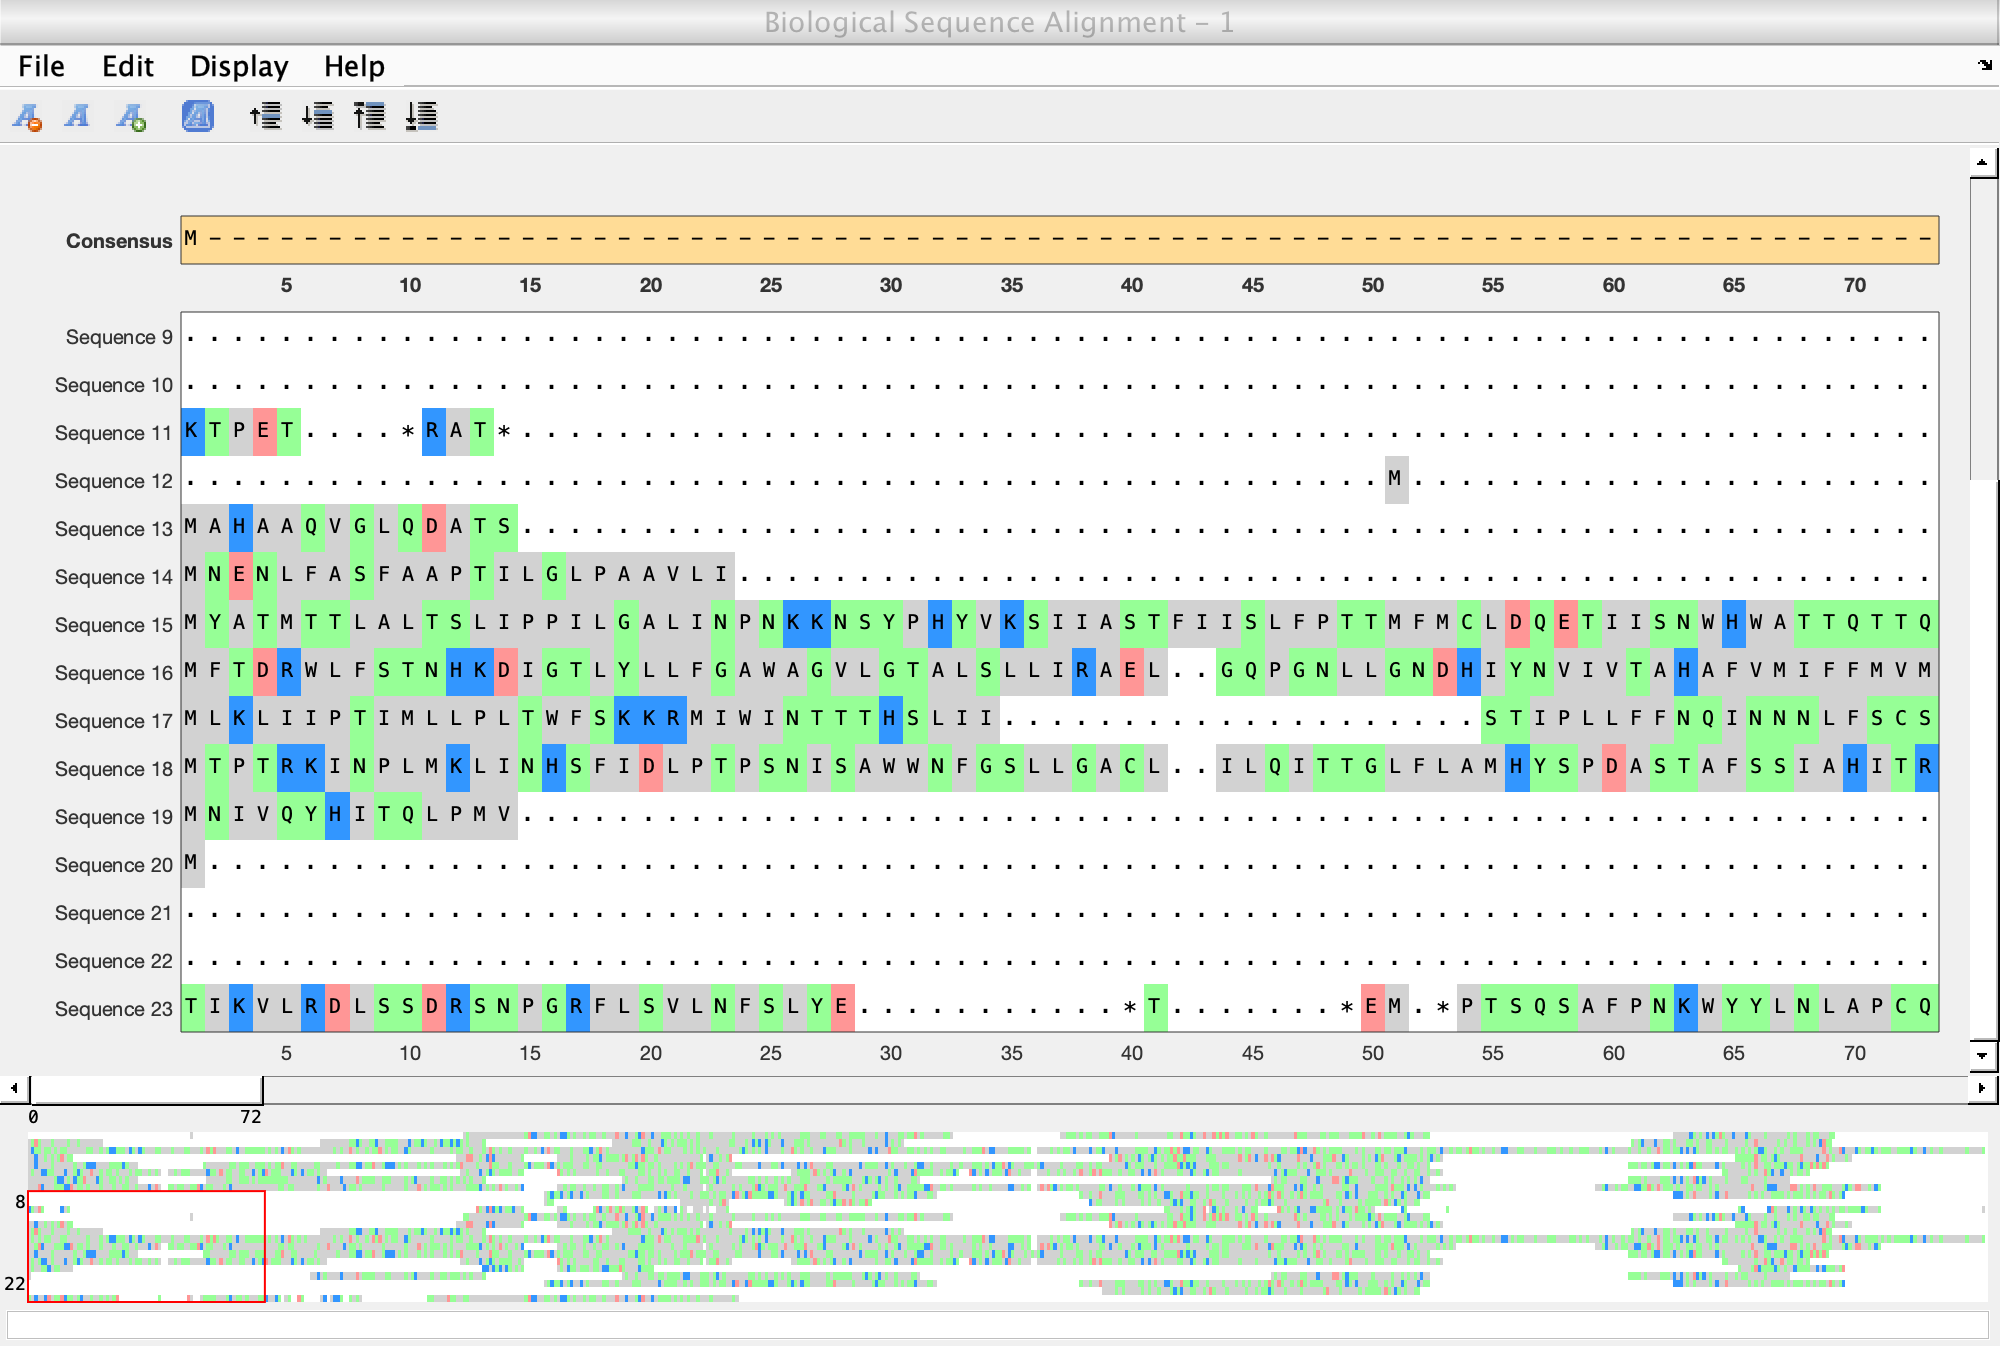

seqalignviewer(ma)

scores = [];
for i=1: length(h_aminoacid)
    for j=1:length(aminoacid)
        scores = [scores; i,j,nwalign(char(h_aminoacid(i,1)), char(aminoacid(j,1)), 'scoringmatrix','blosum30','gapopen',5,'extendgap',5)];
    end
end

length(scores)

ans = 132

tobetested = find(scores(:,3) > 100)

tobetested =      1
    15
    28
    38
    54
    67
    81
    89
   106


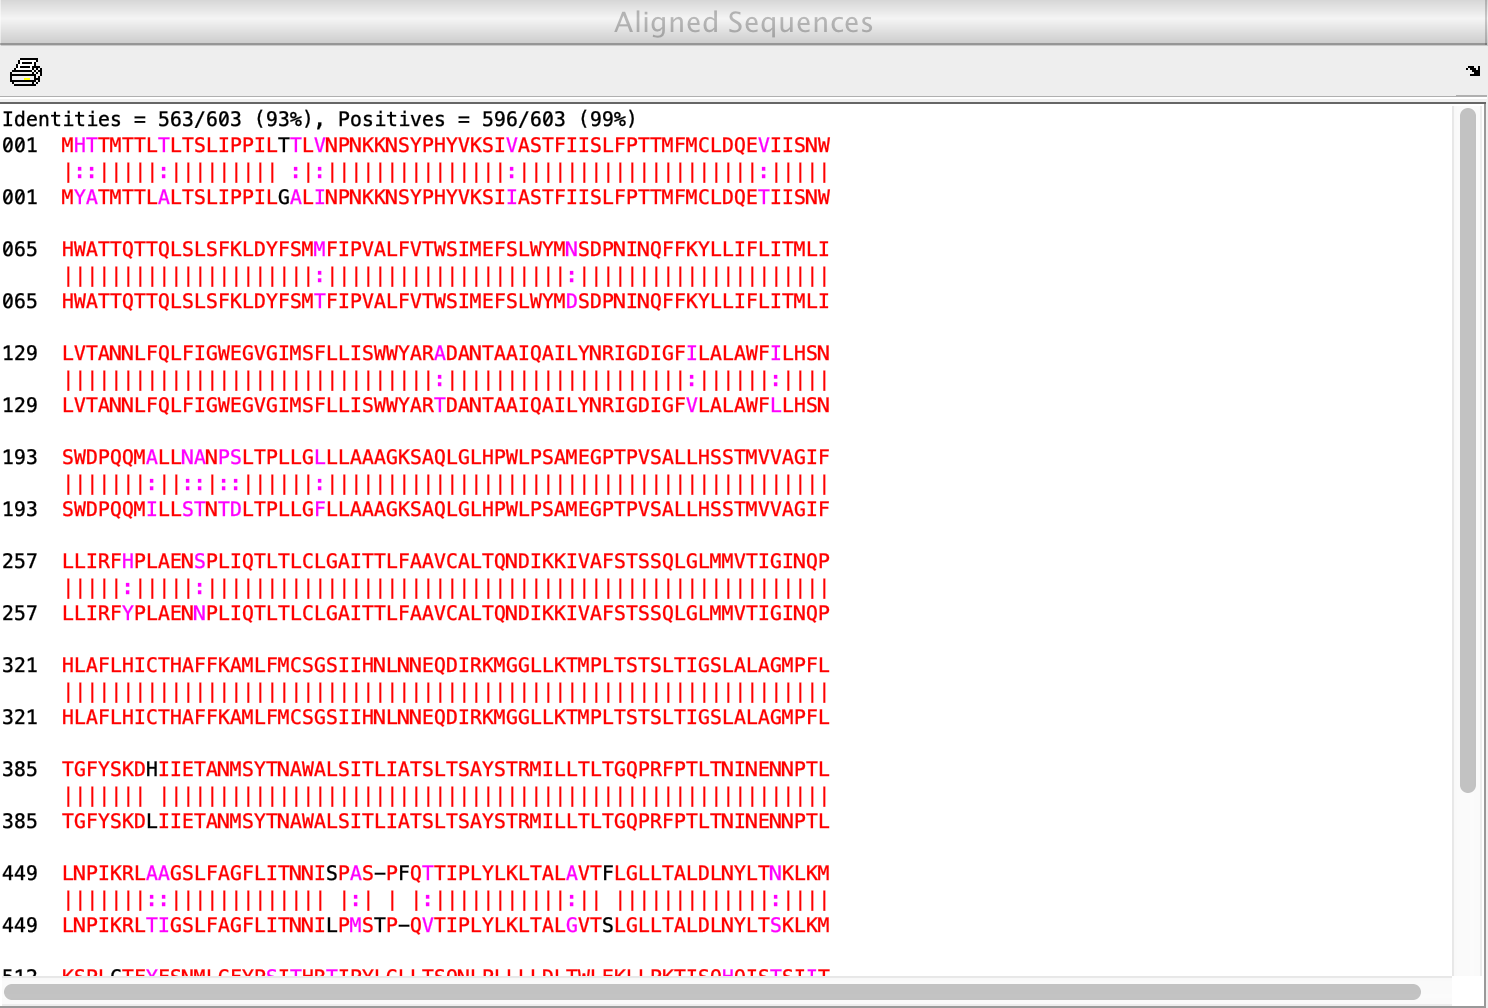

for i=3: 3
    h = scores(tobetested(i),1);
    c = scores(tobetested(i),2);
    human_protein = char(h_aminoacid(h,1));
    chimp_protein = char(aminoacid(c,1));
    [score1, alignment] = nwalign(human_protein, chimp_protein, ...
            'scoringmatrix','blosum30','gapopen',5,'extendgap',5);
         showalignment(alignment)
     %alignment    
    
end

length(char(h_aminoacid(1,1)))

ans = 317

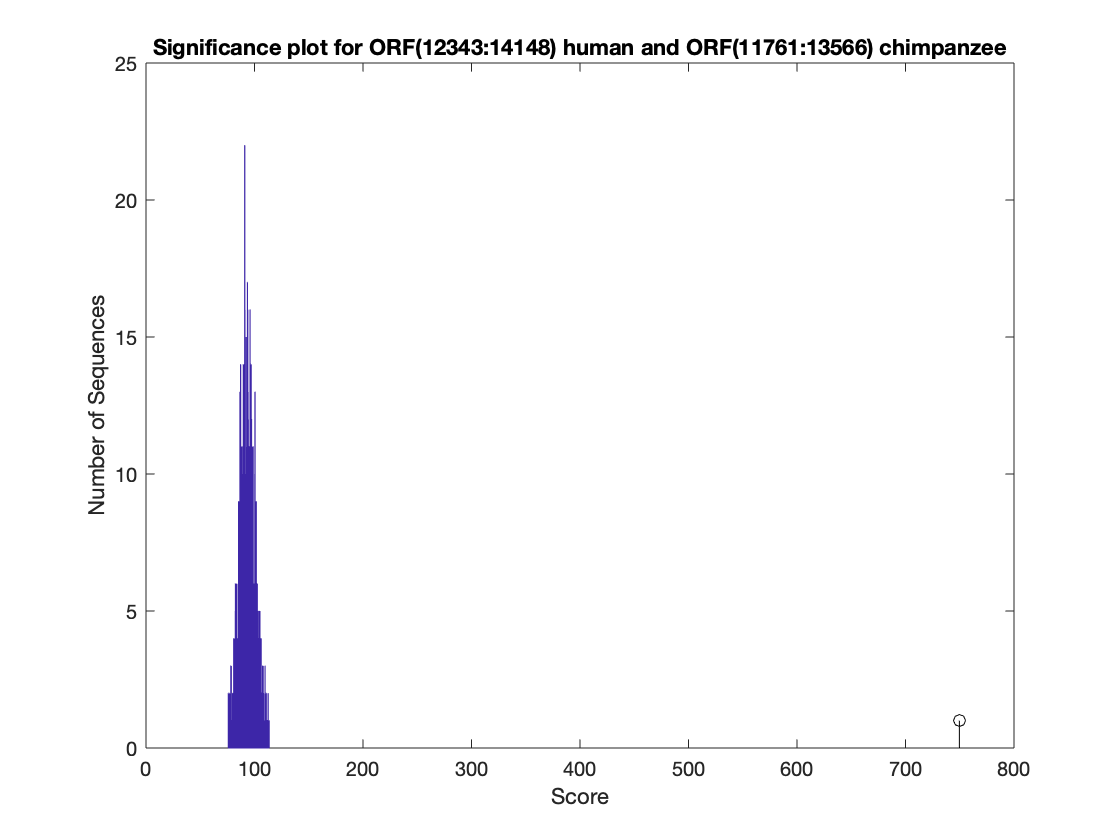

score = 749.6000

titleStr = "Significance plot for ORF(12343:14148) human and ORF(11761:13566) chimpanzee"

for i=3:3
    h = scores(tobetested(i),1);
    c = scores(tobetested(i),2);
    score = scores(tobetested(i),3);
    human_protein = char(h_aminoacid(h,1));
    chimp_protein = char(aminoacid(c,1));
    n = 1000;
    globalscores = zeros(n,1);
    chimpLen = length(chimp_protein);
    for j = 1:n
        perm = randperm(chimpLen);
        globalscores(j) = nwalign(human_protein,chimp_protein(perm),'scoringmatrix','blosum30','gapopen',5,'extendgap',5);
    end
    figure
    buckets = ceil(n/5);
    hist(globalscores,buckets)
    hold on;
    stem(score,1,'k')
    xlabel('Score'); ylabel('Number of Sequences');
    titleStr = strcat('Significance plot for ORF(' ,h_aminoacid(h,2),':',h_aminoacid(h,3), ...
        ') human and ORF(',aminoacid(c,2),':',aminoacid(c,3), ') chimpanzee');
    title(titleStr);
    hold off;
    
    score
    titleStr
end